# Práctica 5 - OFDM

## Definición del sistema

clear; close all, format compact

NFFT  =	128;  % Tamaño de la FFT
df    = 200;  % Separación entre portadoras (Hz)
Fs    =	NFFT*df;  % Frecuencia de muestreo (Hz)
Nf    =	10;  % Numero de portadoras con datos
m_ary =	4;  % Indicador de modulacion digital de cada portadora (QPSK)
SNR_vector = -5:1:15;  % Vector de relaciones SNR en el canal
 
% Generación de los bits a transmitir. Han de ser un multiplo entero de log2(m_ary)*Nf
Nofdm  =  1000;  % Número de símbolos OFDM
txbits = round(rand(1,2*Nf*Nofdm));
 
% Generación de símbolos complejos resultantes de la modulación en QPSK. Se recomienda, aunque no es estrictamente necesario, que los símbolos se agrupen en una matriz de Nf filas y Nofdm columnas
mod = moduladorQPSK(txbits);
mod=reshape(mod,Nf,Nofdm);

## Modulación OFDM

% La modulación OFDM se implementa realizando la transformada inversa de Fourier de una matriz X, que se obtiene de los símbolos complejos a la salida del modulador QPSK, tal como se describe en la teoría. A X se le denomina matriz de coeficientes espectrales, y su dimensión es NFFT filas por Nofdm columnas

% Creación de la matriz X, de componentes espectrales, para la IFFT

%  Incialización a cero
X = zeros(NFFT, Nofdm);

%  Asignación de los símbolos moduladores al espectro positivo
Nstart = 28+1;
Nend = 37+1;  
X(Nstart:Nend,:) = mod;
%
%  Asignación de los símbolos moduladores en orden inverso y conjugados al espectro negativo. Describa lo que realiza la función flipud.
X(NFFT/2+2:NFFT,:) = flipud(conj(X(2:NFFT/2,:)));

La función *flipud* recibe un vector y devuelve ese mismo vector con las filas invertidas. 

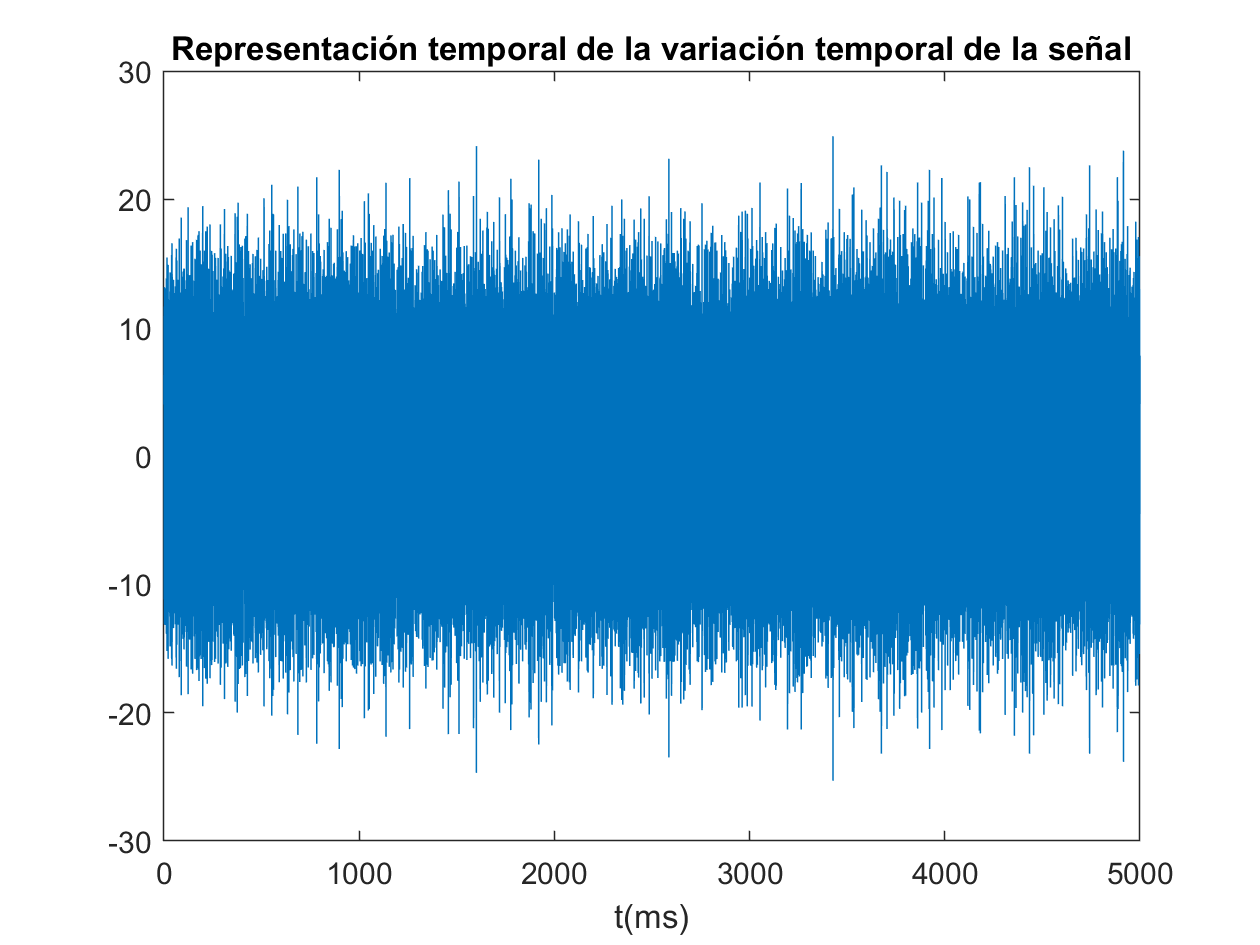

% Generación del vector de muestras temporales reales x como resultado de la modulación OFDM. Léase la documentación de las funciones IFFT y FFT de MATLAB
x = ifft(X,NFFT,"symmetric")*NFFT; % Señal transmitida, que tiene que ser real

% En esta práctica no se añade prefijo cíclico

% Transformación de x en un vector fila
x = reshape(x, 1, []);

% Representación de gráficas temporales
% Represente dos gráficas temporales. En la primera se debe representar la señal x durante un intervalo de tiempo correspondiente a varios símbolos OFDM, a elegir por el alumno. En la segunda represente la variación de la potencia en función del tiempo, superponiendo sobre la gráfica las rectas de potencia media y potencia de pico en ese intervalo de tiempo. Calcule el PAPR en dB e indique su valor en el título de la gráfica.

figure;
% representación de la variación temporal de la señal
t = (0:1:Nofdm*NFFT-1)*(1/Fs)*1e3;
plot(t,x(1:NFFT*Nofdm));
xlabel('t(ms)');
title("Representación temporal de la variación temporal de la señal")


figure;
% representación de la variación temporal de la potencia, superponiendo las rectas que indican la potencia media y la de pico. 
P = x(1:NFFT*Nofdm).^2; % Potencia de la señal
Pmedia = mean(P); % Potencia media
Ppico = max(P); % Potencia de pico
papr_dB = 10*log10(Ppico/Pmedia) % PAPR en dB

papr_dB = 12.0450

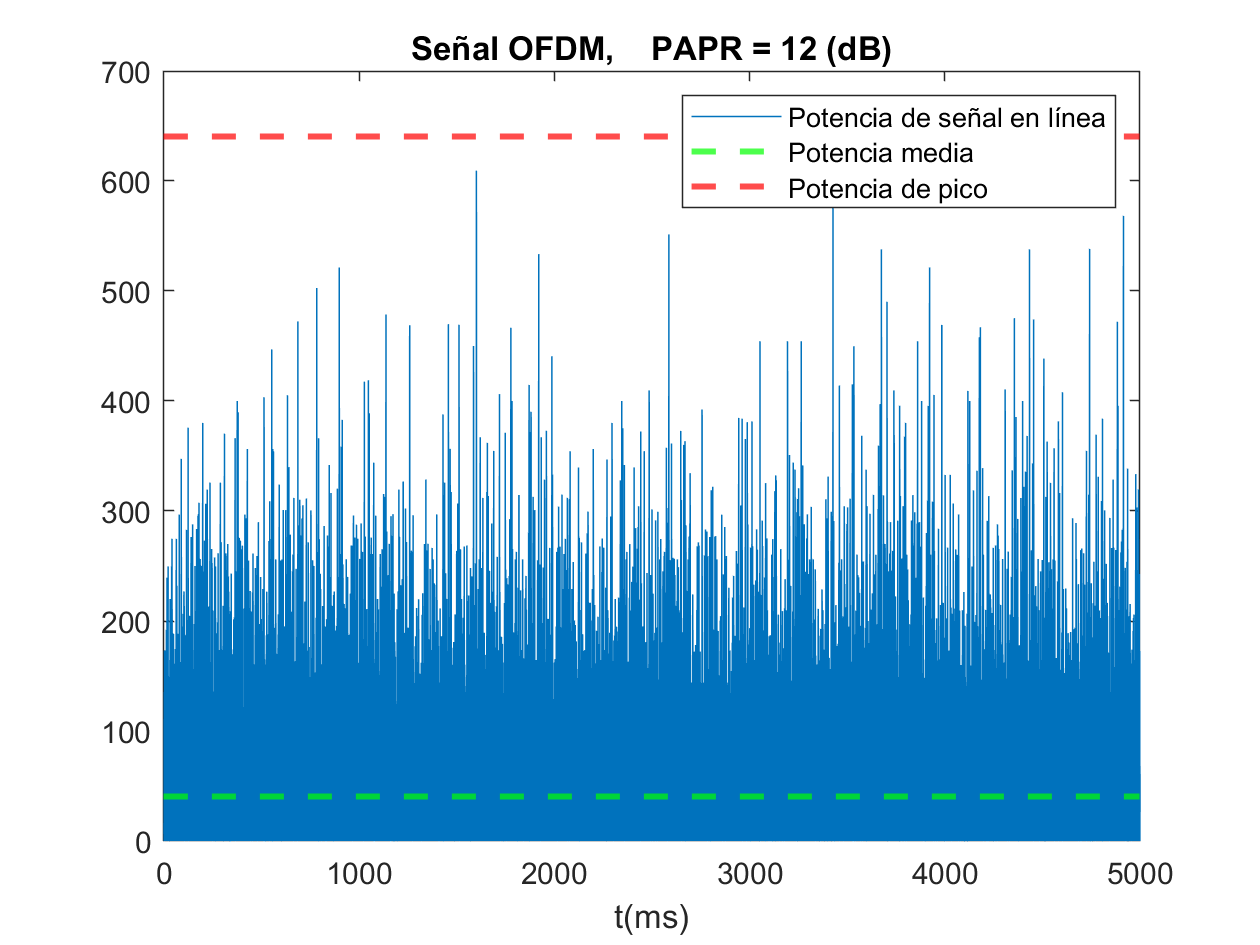

plot(t,P);
hold on;
yline(Pmedia,"--g","lineWidth",2);
yline(Ppico,"--r","lineWidth",2);
xlabel('t(ms)');  
legend('Potencia de señal en línea', 'Potencia media', 'Potencia de pico');  
title(['Señal OFDM,    PAPR = ' num2str(round(papr_dB,1)), ' (dB)']);

## Canal y RX

% Se abre bucle de SNR:
for i=1:length(SNR_vector)

CANAL

SNR=SNR_vector(i);

% Se añade ruido para conseguir el SNR deseado sobre la banda de Nf subportadoras Factor de ancho de banda, fb ¿Qué significa y para qué se utiliza
fb = 10*log10( (NFFT/2)/Nf );
y  = awgn(x,SNR-fb,'measured');

RX

%Demodulación OFDM para obtener los simbolos recibidos. La demodulación es el proceso inverso a la modulación, básicamente realizar una FFT de la señal recibida.
% Transformación del vector y en una matriz de NFFT filas y Nofdm columnas
y = reshape(y, NFFT,Nofdm);

% Implementación de la FFT para demodular la señal OFDM
Y = fft(y,NFFT)/NFFT;

% Selección de la señal
Y = Y(Nstart:Nend,:);

% Demodulación de las señales extraidas del demodulador OFDM para recuperar bits
Y = reshape(Y,1,[]);

% Demodulacion QPSK
rxbits= demoduladorQPSK(Y);
 
% Cálculo de BER
BER(i) = sum(abs(txbits-rxbits))/size(txbits,2);

% Se cierra bucle de SNR
end

## Curvas de BER

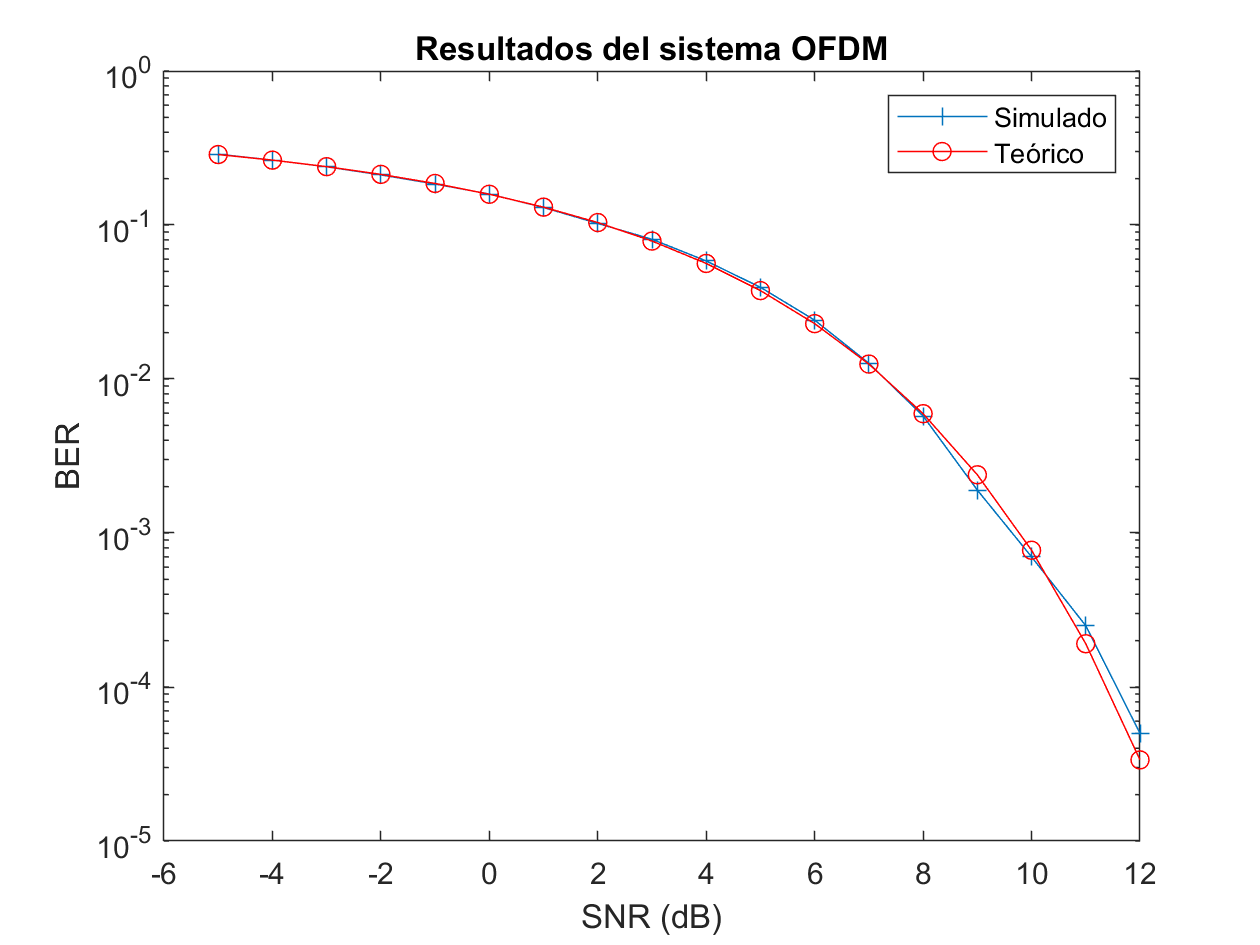

%  Para el cálculo de BER vs SNR en QPSK 
gamma  = 10.^((SNR_vector-3)/10);  
BERTeo = qfunc(sqrt(2*gamma));
BERTeo(find(BERTeo<1e-5)) = NaN;  

figure;
semilogy(SNR_vector, BER, '-+');   
hold on;
semilogy(SNR_vector, BERTeo, '-rO');
grid on;
legend('Simulado','Teórico')
xlabel('SNR (dB)');  ylabel('BER');
title('Resultados del sistema OFDM');

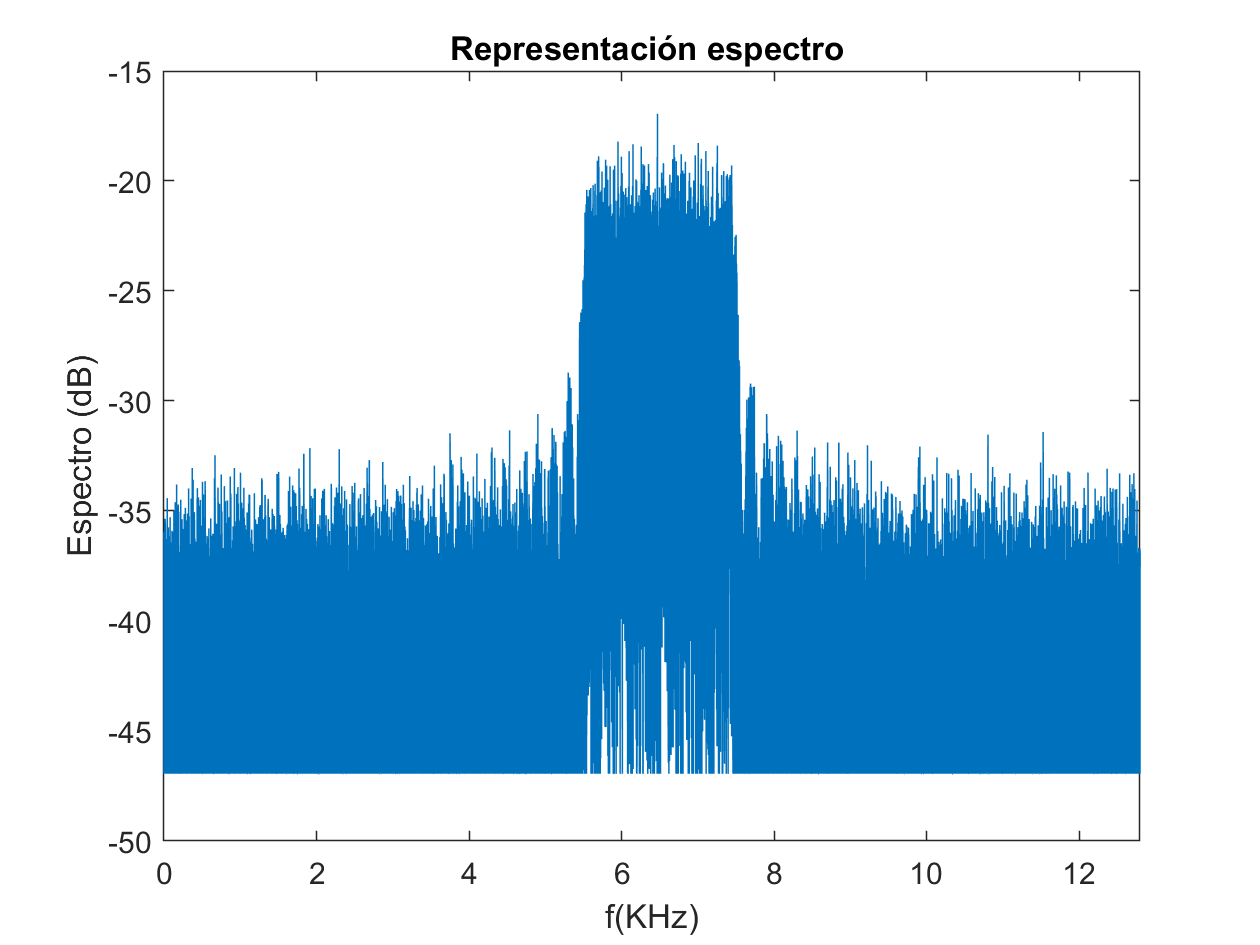


%% Representación espectral

%%Para una relación señal ruido de 15 dB en la banda donde hay señal,       
% represente el espectro real de la señal en línea, en dB, únicamente frecuencias positivas, 
% lo que se vería en un analizador de espectros. El eje de frecuencias debe estar marcado en KHz.
SNR = 15;
y_snr15 = awgn(x,SNR-fb,'measured');
df_symb = df/Nofdm;
NFFT_symb = NFFT*Nofdm;

% Vector de frecuencias
frec = (0:1:NFFT_symb-1)*df_symb;

% FFT
Y_snr15 = fft(y_snr15,NFFT_symb)/NFFT_symb;

% Vector de amplitudes de señal en línea
XdB = 20*log10(abs(Y_snr15));

% Limitación del margen dinámico
XdB(find(XdB<max(XdB)-30)) = max(XdB)-30;

% Representación en frecuencia de la señal real en línea
figure;
plot(frec*1e-3, XdB);
xlabel('f(KHz)');  
xlim([0 NFFT/2*df*1e-3]);
ylabel('Espectro (dB)');
title("Representación en frecuencia de la señal real en línea");